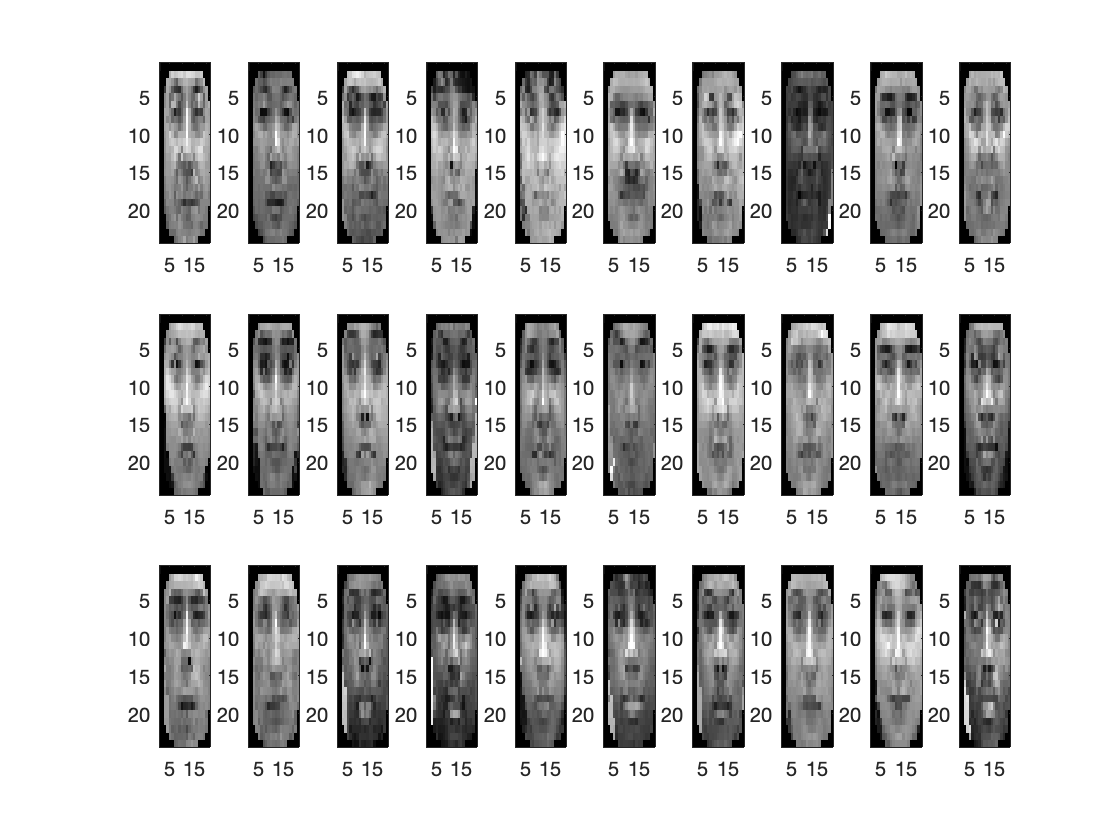

data = load("data.mat");
face = data.face;
f_neutral = face(:,:,1:3:end);
f_exp = face(:,:,2:3:end);
f_illum = face(:,:,3:3:end);

for i =1:30
    subplot(3,10,i);
    imagesc(f_neutral(:,:,i));
    imagesc(f_exp(:,:,i));
    imagesc(f_illum(:,:,i));
    colormap gray;
end

%Convert image matrices to arrays
n_new = zeros(200,24*21);
e_new = zeros(200,24*21);
i_new = zeros(200,24*21);

for i = 1:200
    x = f_neutral(:,:,i);
    y = f_exp(:,:,i);
    p = f_illum(:,:,i);
    n_new(i,:) = x(:)';
    e_new(i,:) = y(:)';
    i_new(i,:) = p(:)';
end
%Finding the means and centering the data

n_mean = mean(n_new,1);
e_mean = mean(e_new,1);
i_mean = mean(i_new,1);

n_centered = n_new - ones(200,1)*n_mean;
e_centered = e_new - ones(200,1)*e_mean;
i_centered = i_new - ones(200,1)*i_mean;

combined = [n_new;e_new;i_new];

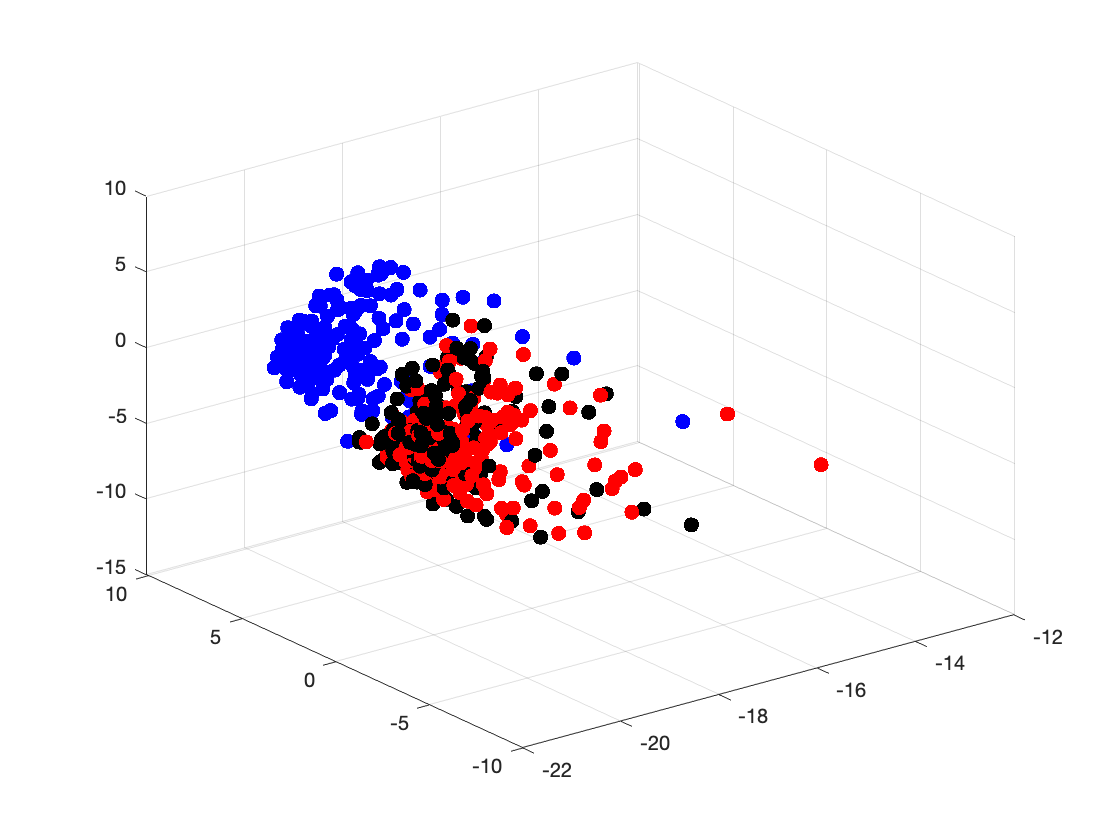

%PCA

D1 = 1:200;
D2 = 201:400;
D3 = 401:600;
nPCA = 35;
[U,Sigma,V] = svd(combined',"econ");
z = combined*U(:,1:nPCA);
figure;
hold on; grid;
plot3(z(D1,1),z(D1,2),z(D1,3),".","Markersize",20,"color","k");
plot3(z(D2,1),z(D2,2),z(D2,3),".","Markersize",20,"color","r");
plot3(z(D3,1),z(D3,2),z(D3,3),".","Markersize",20,"color","b");
view(3);

%Splitting the data for neutral and smiling faces into training and test
%sets for both

n_train = z(1:200,:);
e_train = z(201:400,:);
i_train = z(401:600,:);

train_set = zeros(200,nPCA,2)

train_set = train_set(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

test_set = zeros(200,nPCA,1);

train_set(:,:,1) = n_train;
train_set(:,:,2) = e_train;
test_set(:,:,1) = i_train;

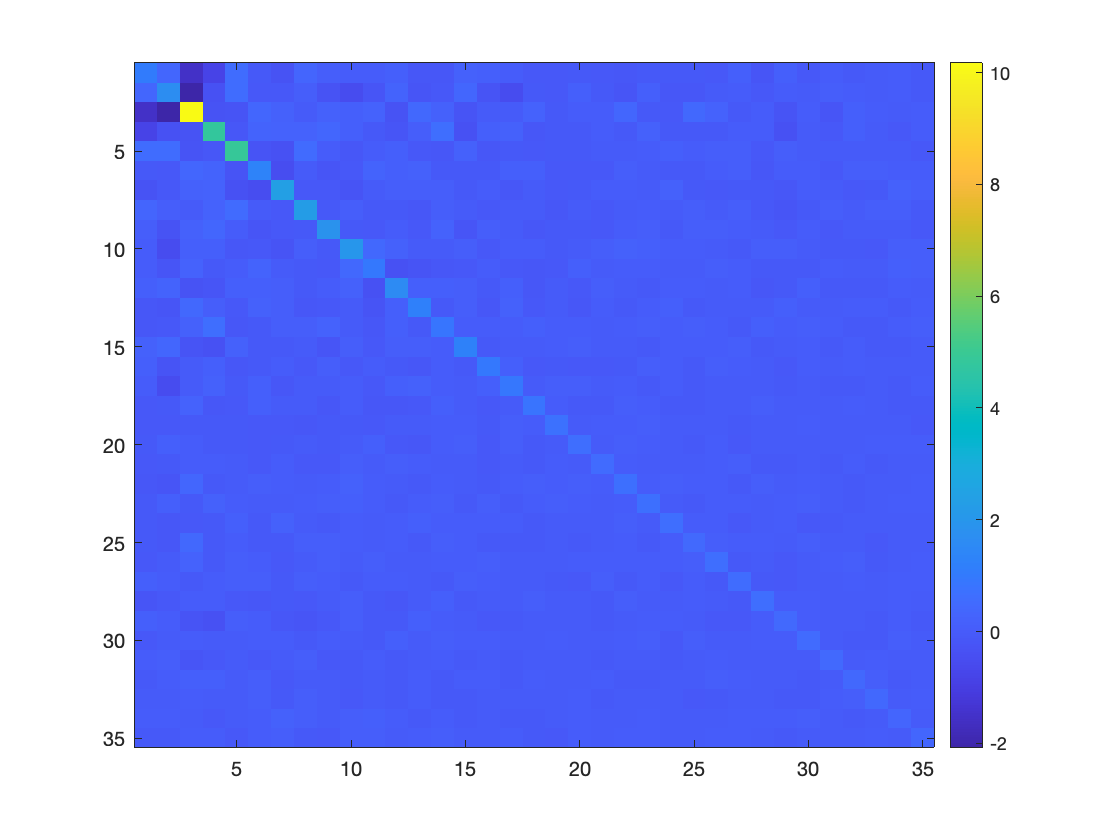

%Bayesian Decision Classifier
n_mu = mean(n_train,1);
e_mu = mean(e_train,1);
norm(n_mu-e_mu);

n_train_cen = n_train - ones(200,1)*n_mu;
e_train_cen = e_train - ones(200,1)*e_mu;

n_cov = n_train_cen'*n_train_cen/200;
e_cov = e_train_cen'*e_train_cen/200;

figure;
imagesc(n_cov);
colorbar;

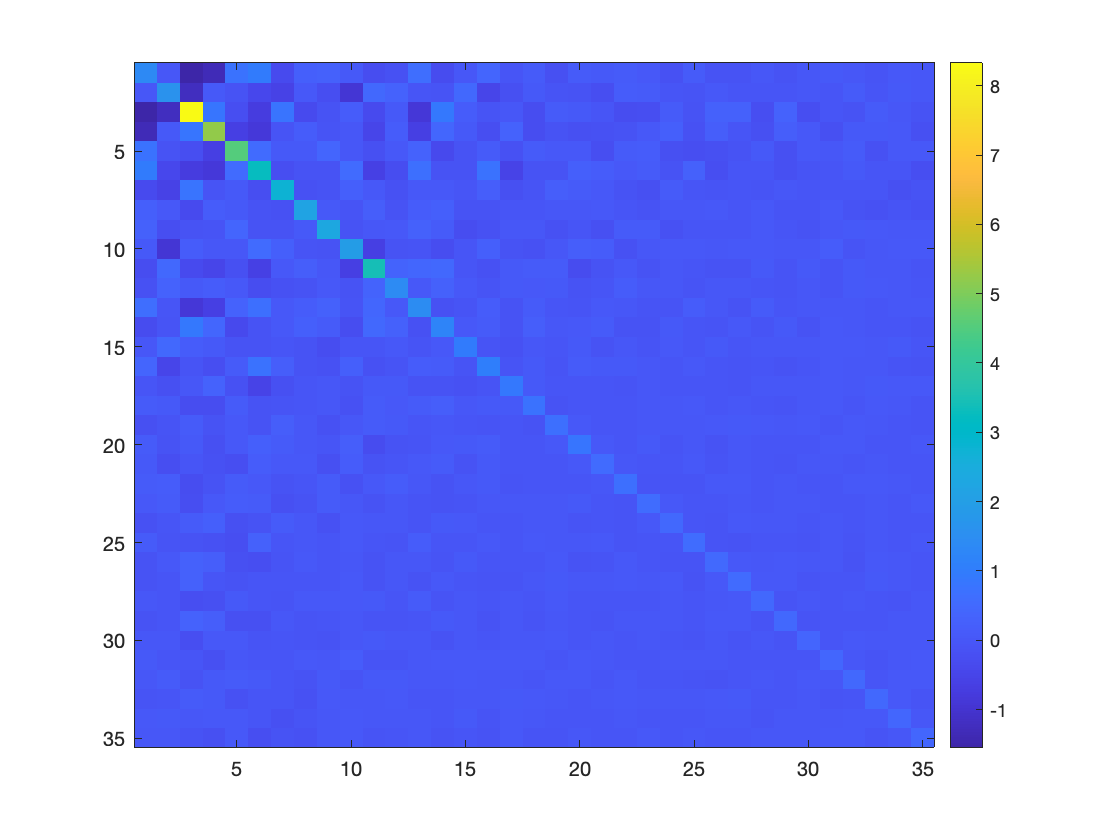

figure;
imagesc(e_cov);
colorbar;

n_inv = inv(n_cov);
e_inv = inv(e_cov);

f1 = @(x)(1/((det(n_cov))^0.5))*exp((-0.5)*(x-n_mu')'*n_inv*(x-n_mu'));
f2 = @(x)(1/((det(e_cov))^0.5))*exp((-0.5)*(x-e_mu')'*e_inv*(x-e_mu'));
label = zeros(200,1);
for i = 1:200
    q=f_illum(:,:,i);
    s = q(:)'*U(:,1:nPCA);
    label(i) = sign(f1(s')-f2(s'));
end
n_pred = find(label > 0);
e_pred = find(label < 0);
fprintf("Neutral Face Prediction = %d, Smiling Face Prediction = %d, Neutral Face Accuracy %d\n",...
    length(n_pred), length(e_pred), length(n_pred)/200);

Neutral Face Prediction = 117, Smiling Face Prediction = 83, Neutral Face Accuracy 5.850000e-01


%k-nearest neighbors on illumination test set
k = 40;
n_pred_k = 0;
e_pred_k = 0;
for i = 1:200
    x_diff = [];
    class = [];
    for y = 1:2
        for j = 1:200
            for l = nPCA
                x_norm = 0;
                x_dist = (train_set(j,l,y) - test_set(i,l,1))^2;
                x_norm = x_norm + x_dist;
            end
            x_norm = sqrt(x_norm);
            x_diff = [x_diff, x_norm];
            class = [class,y];
        end
    end
    diff_table = array2table(x_diff);
    x_diff = class;
    class_table = array2table(x_diff);
    dist_table = [class_table;diff_table];
    dist_table = rows2vars(dist_table);
    dist_table(:,"OriginalVariableNames") = [];
    sorted = sortrows(dist_table,2);
    nearest = head(sorted,k);
    nearest_array = table2array(nearest);
    pred_class = mode(nearest_array, 1);
    if (pred_class(1) == 1)
        n_pred_k = n_pred_k + 1;
    else
        e_pred_k = e_pred_k + 1;
    end
end
accuracy_rate = n_pred_k/200;
fprintf("Neutral Prediction = %d, Smiling Prediction = %d, Neutral Accuracy %d\n",...
n_pred_k, e_pred_k, accuracy_rate);

Neutral Prediction = 132, Smiling Prediction = 68, Neutral Accuracy 6.600000e-01
